# **SharpIRTest.mlx **

## *Test Sharp IR Sensors*

Izzie Abilheira, Chris Allum, OJ Bradley, Oscar De la Garza, Nabih Estefan Diaz, and Maya Sivanandan - 4/20/2021 - Rev. 0

clc     % clear command window
clear   % clear MATLAB workspace

addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/ACT/

**Set up robot control system** (code that runs once)

% Create Arduino and Arduino-velocity servo ref-objects
disp('note: It takes about 10 seconds to download code to RsapPi');

note: It takes about 10 seconds to download code to RsapPi


[robotPi, blinkLED]= SETUP_pi('192.168.16.66');

[dev1, dev2] = SETUP_adc(robotPi);

% Turn board LED on and off to signal program has started
Blink(robotPi,blinkLED,10);
disp('Warning! Furby Rover Active!'); 

Warning! Furby Rover Active!



% Configure test loop to collect n data points.

nTests = input(['Enter number of range test positions, followed by enter: ']);
rawSharpData = zeros(nTests,5);

% Create a variable to hold experimental position data
    positionData = zeros(nTests,1);
    
    r = rateControl(0.1);              % create a 0.1Hz loop rate
    reset(r)                            % reset loop time to zero

### Run Robot Control Loop

This code runs repeatedly

controlFlag = 1;
while(controlFlag < nTests+1) 
    
    rawAdcData = SENSE_adc(dev1, dev2);
    rawSharpData(controlFlag,1:5) = rawAdcData(1,1:5);
    
    % store experimental commanded vs. actual data
    positionData(controlFlag, 1) = input('Enter actual distance (cm): ');
    gtest = input('move Sharp to new range, type G, then hit ENTER', 's');
    waitfor(r); % wait for loop cycle to complete
    controlFlag = controlFlag + 1; % increment loop
end

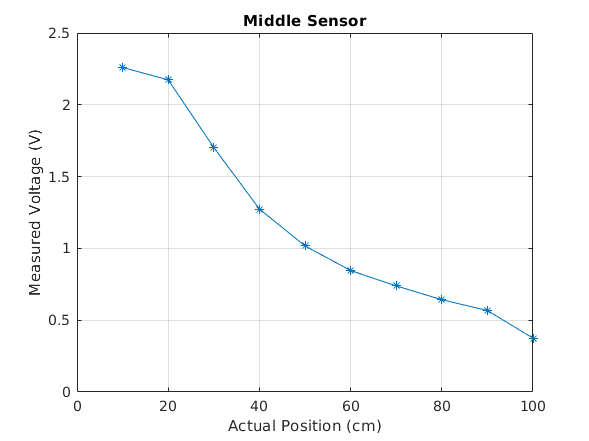

%Plot and store commanded position data vs. actual position
plot(positionData(:,1),rawSharpData, '-*')
xlabel('Actual Position (cm)');
ylabel('Measured Voltage (V)');
legend('A0','A1','A2','A3','2A0')
grid

save /IRData positionData rawSharpData


load ./test_code/IRData.mat;

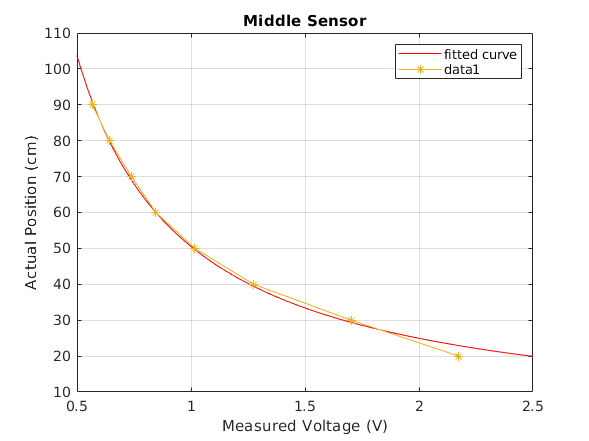

f =      General model:
     f(x) = 1/(a*x+b)
     Coefficients (with 95% confidence bounds):
       a =     0.02029  (0.01868, 0.02189)
       b =  -0.0005032  (-0.001617, 0.0006107)

x = rawSharpData(2:end-1,3);
y = positionData(2:end-1,1);

plot(x,y, '-*')
ylabel('Actual Position (cm)');
xlabel('Measured Voltage (V)');
title("Middle Sensor")
grid

customFit = fittype("1/(a*x+b)");

f = fit(x,y,customFit)

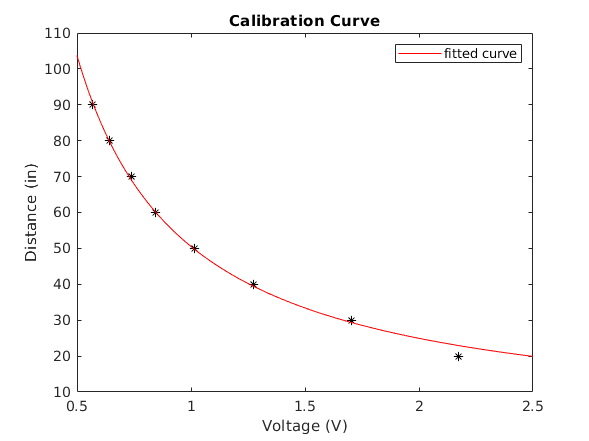


figure
plot(x,y,"*k"),hold on
plot(f,"-r")
xlabel("Voltage (V)")
ylabel("Distance (in)")
title("Calibration Curve")

rawDist = SENSE_IR(dev1, dev2);



object =    75.1270   80.1270
   17.1030   50.3613
         0   39.1080
  -10.7700   35.0721
  -26.4955   31.4955


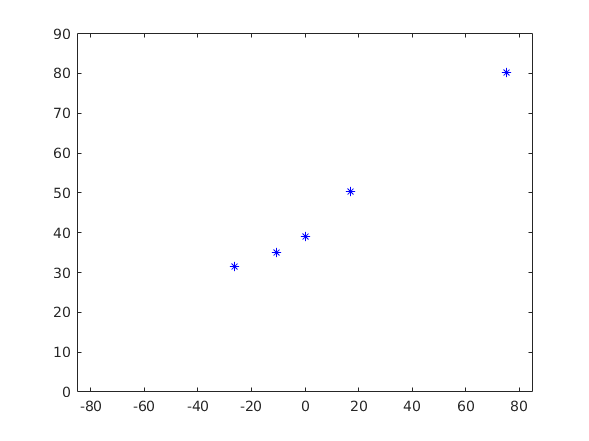


figure
plot(object(:,1),object(:,2),"*b")
axis([-max_x-10 max_x+10 0 max_y+10])

positionData(:,2) = 1./(positionData(:,1)+0.42)

positionData =    10.0000    0.0960         0         0         0
   20.0000    0.0490         0         0         0
   30.0000    0.0329         0         0         0
   40.0000    0.0247         0         0         0
   50.0000    0.0198         0         0         0


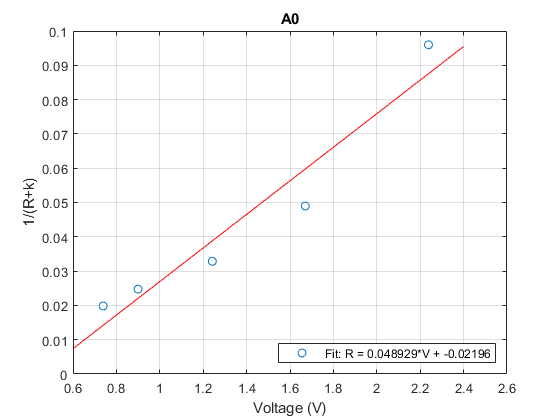

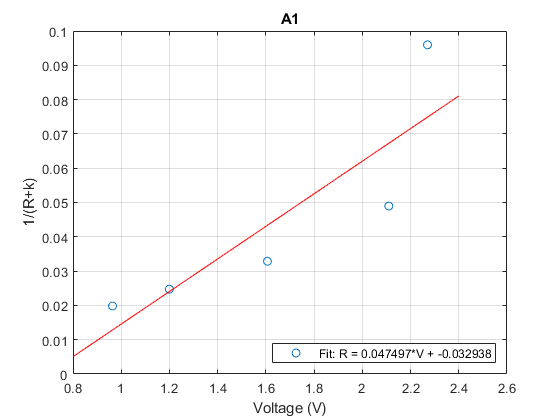

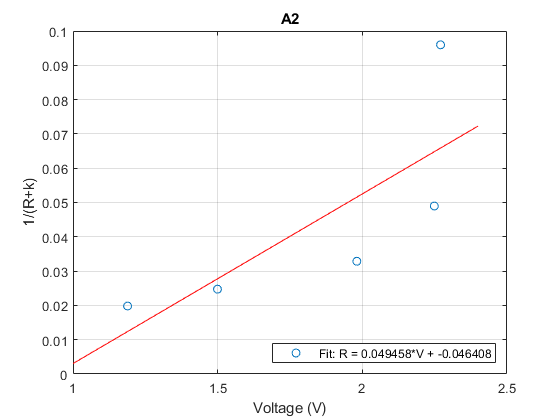

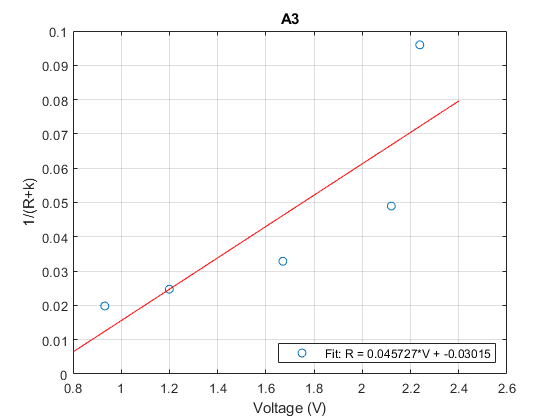

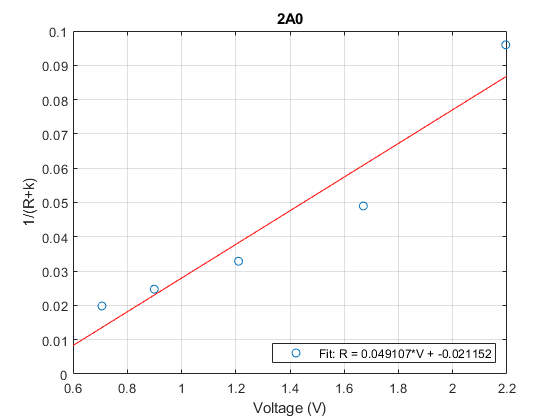


for i=1:5
    f = fit(rawSharpData(:,i),positionData(:,2), 'poly1');
    coeff = coeffvalues(f);
    m = num2str(coeff(1));
    b = num2str(coeff(2));
    eq = append('R = ',m,'*V + ',b);
    figure
    plot(rawSharpData(:,i), positionData(:,2), 'o');
    hold on
    plot(f)
    hold off
    xlabel('Voltage (V)')
    ylabel('1/(R+k)')
    if i <= 4
        pin = num2str(i-1);
        label = append('A',pin);
    elseif i == 5
        label = '2A0';
    end
    title(label)
    legend(sprintf('Fit: %s',eq), 'Location','southeast')
    grid
end


% positionData
% rawSharpData
% 
% f1 = fit(rawSharpData(:,1),positionData(:,2), 'poly1')
% 
% plot(rawSharpData(:,1), positionData(:,2), 'o');
% hold on
% plot(f1)
% hold off
% xlabel('Voltage (V)')
% ylabel('1/(R+k)')

% legend(sprintf('Fit: %s', eq), 'Location','southeast')
% grid

**Clean Shutdown**

*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = robotPi`

## `h.execute('sudo shutdown -h now')`